## [Logistic Regression](https://apmonitor.com/pds/index.php/Main/LogisticRegression)

Logistic regression is a machine learning algorithm for classification. In this algorithm, the probabilities describing the possible outcomes of a single trial are modeled using a logistic function.

Logistic regression makes a binary classification prediction based on the sigmoid function with *n* input features, $x_1 \ldotp \ldotp \ldotp x_n$.


$$p=\frac{1}{1+e^{-\left(\beta_0 +\beta_1 x_1 +\ldotp \ldotp \ldotp +\beta_n x_n \right)} }$$


The $\beta_i$ are coefficients that can be determined from a stochastic gradient descent or other optimization on the training dataset. The desired classification is either a 0 or 1, so the probability calculated with the sigmoid function is rounded to the nearest value.

**Advantages:** Logistic regression is designed for this purpose (classification), and is most useful for understanding the influence of several independent variables on a single outcome variable.

**Disadvantages:** Assumes all predictors are independent of each other, and assumes data set is free of missing values.

#### **Optical Character Recognition with Logistic Regression**

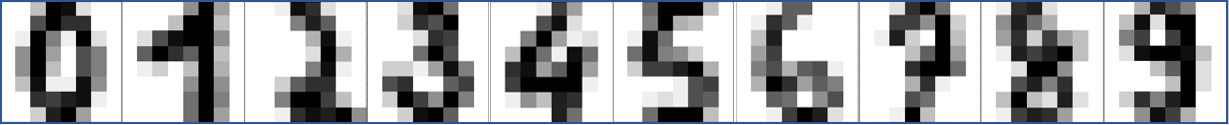

Optical character recognition (OCR) is a method used to convert images of text into machine-readable text. It is typically used to process scanned documents and recognize the text in the images. Logistic regression is a type of machine learning model that can be used for classification tasks. In the context of OCR, logistic regression could be trained to recognize characters in images of text.

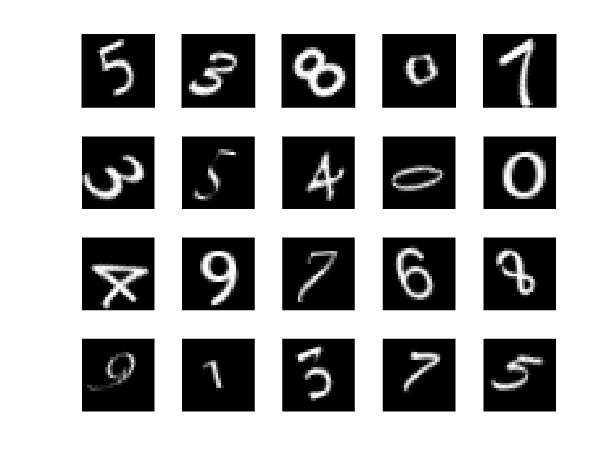

% Import dataset of numbers
digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

% Show example of dataset
figure;
perm = randperm(10000,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

n_samples = length(imds.Files);

% Extract the images into a matrix
X_data = cell(n_samples, 1);
for i = 1:n_samples
    [X_data{i}] = deal(reshape(readimage(imds,i)',[1,28*28]));
end
X_data = cell2mat(X_data);

% Save the labels of the images
Y_data = imds.Labels(1:n_samples);

% Split the data 50% training adn 50% testing
[trainInd,~,testInd] = dividerand(n_samples,0.5,0,0.5);

X_Train = X_data(trainInd,:);
X_Test = X_data(testInd,:);
Y_Train = Y_data(trainInd,:);
Y_Test = Y_data(testInd,:);

% Create fit
classifier = fitcecoc(array2table(im2double(X_Train)),Y_Train,'FitPosterior',true);

formula = 'Y_Train ~ Var2';
classifier = fitglm(table(Y_Train, im2double(X_Train)), formula);

Error using classreg.regr.FitObject/selectVariables
Predictor variables must be numeric vectors, numeric matrices, or categorical vectors.

Error in classreg.regr.TermsRegression/selectVariables (line 259)
            model = selectVariables@classreg.regr.ParametricRegression(model);

Error in 



% Evaluate the model performance on the test set
y_pred = predict(classifier,array2table(im2double(X_Test)));
accuracy = mean(y_pred == Y_Test);
fprintf("Accuracy: %.2f\n", accuracy);

Below is an example that also shows a number from the test set that is evaluated with the Logistic Regression classifier.

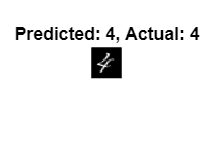

% Select random nummber image
n = randi([0,n_samples],1);

% Get the prediction
reshape(readimage(imds,n)',[1,28*28]);
yp = predict(classifier,im2double(reshape(readimage(imds,n)',[1,28*28])));

% Display the image with the prediction
figure;
imshow(imds.Files{n})
titleText = "Predicted: " + string(yp) + ", Actual: " + string(imds.Labels(n));
title(titleText, 'FontSize', 12)

#### Logistic Regression Programming

Using only MATLAB code (not a machine learning package), create a Logistic Regression classifier. First develop the code to test 2 features. Use the source code blocks as needed.

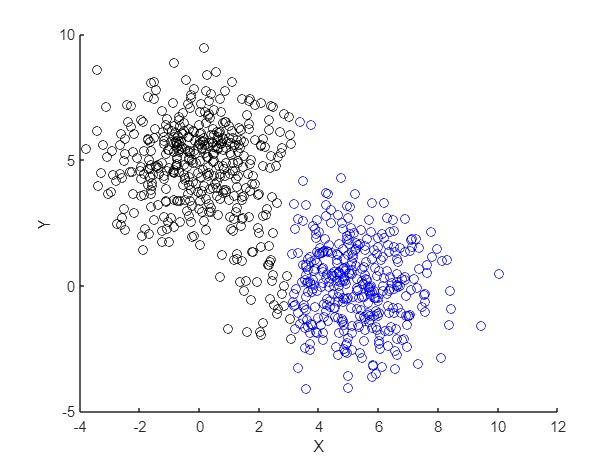

% Create Data
% Set parameters for data
n_samples = 800;
n_features = 2;
centers = [0, 5; 5, 0];
cluster_std = 1.5;

% Create matrixes to hold data
data_val = zeros(n_samples, n_features);
label = zeros(n_samples, 1);

% Create the random data based on previous inputs
for i = 1:2
    idx = ((i-1)*n_samples/2 + 1) : (i*n_samples/2);
    data_val(idx, :) = bsxfun(@plus, centers(i,:), cluster_std*randn(length(idx), n_features));
    label(idx) = i;
end

% Combine the X and Y data
tbl = [array2table(data_val) array2table(label)];
tbl.Properties.VariableNames = ["X","Y","label"];

% Plot Data
figure;
cmap = [0 0 0; 0 0 1];
colormap(cmap)
scatter(tbl,"X","Y","ColorVariable",true);

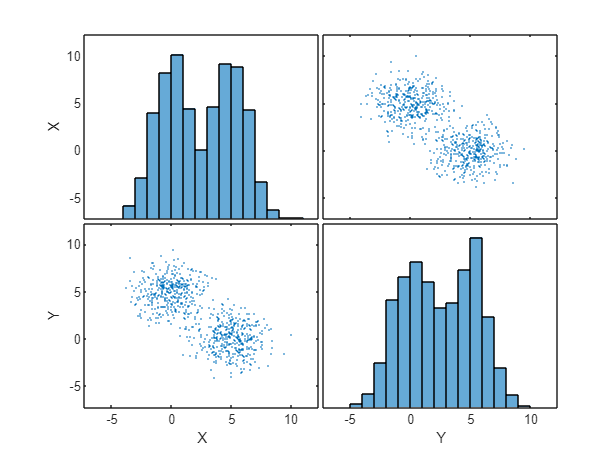


% Plot matrix
figure;
[~, ax, ~, ~, ~] = plotmatrix(table2array(tbl(:,1:end-1)));

for i = 1:2
    xlabel(ax(2,i), tbl.Properties.VariableNames{i})
    ylabel(ax(i,1), tbl.Properties.VariableNames{i})
end

Split data into train (80%) and test (20%) sets.

% Split the data 80% training and 20% testing
[trainInd,~,testInd] = dividerand(n_samples,0.5,0,0.2);

train = tbl(trainInd,:);
test = tbl(testInd,:);

Create a function to make a prediction with coefficients.


$$p=\frac{1}{1+e^{-\left(\beta_0 +\beta_1 x_1 +\ldotp \ldotp \ldotp +\beta_n x_n \right)} }$$


See function section below to view this function.

Update coefficients for the intercept $\beta_0$ with


$$\beta_0 =\beta_0 +l_{\textrm{rate}} \left(\textrm{err}\right)\overset{\wedge }{y} \left(1-\overset{\wedge }{y} \right)$$


and for the feature coefficients $\beta_{i+1}$ with


$$\beta_{i+1} =\beta_{i+1} +l_{\textrm{rate}} \left(\textrm{err}\right)\overset{\wedge }{y} \left(1-\overset{\wedge }{y} \right)x_i$$


where $l_{\textrm{rate}}$ is the learning rate (use 0.3), err is the error (difference) between the measured label y and the predicted label $\overset{\wedge }{y}$, and $x_i$ is the input feature. Continue for 100 epochs (iteration updates of β) and plot the loss function.

% Set parameters for learning model
l_rate = 0.25;
n_epoch = 100;

% Run the model
loss = zeros(n_epoch,1);
beta = [0.0; 0.0; 0.0];
for epoch = 1:n_epoch
    sum_error = 0;
    for i = 1:size(train,1)
        row = table2array(train(i,:));
        x = row(1:end-1); % input features
        y = row(end)-1;     % output label
        yhat = prediction(row, beta);
        error = y - yhat;
        sum_error = sum_error + error^2;
        beta(1) = beta(1) + l_rate * error * yhat * (1.0 - yhat);
        beta(2) = beta(2) + l_rate * error * yhat * (1.0 - yhat) * x(1);
        beta(3) = beta(3) + l_rate * error * yhat * (1.0 - yhat) * x(2);
    end
    loss(epoch) = sum_error; % Save error to loss matrix
end

disp('Coefficients:')

Coefficients:


disp(beta)

    0.7599
    2.8755
   -3.0178



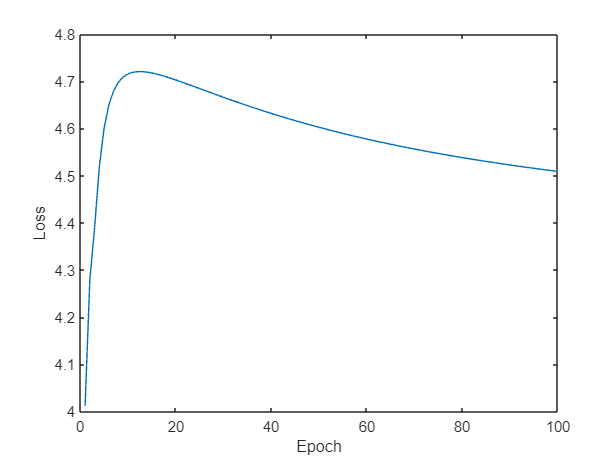

plot(loss);
xlabel('Epoch');
ylabel('Loss');

Occasionally, the loss function will increase for a time and this could be due to a variety of factors. If the learning rate is too large the optimization process can overshoot the minimum, leading to divergence. Though if the learning rate is to small the convergence may be slow. Also the noisier the data is the more the loss function tends to fluctuate. Scaling the data can help alleviate that problem. 

Test the logistic regression model on the remaining 20% the data not used for training.

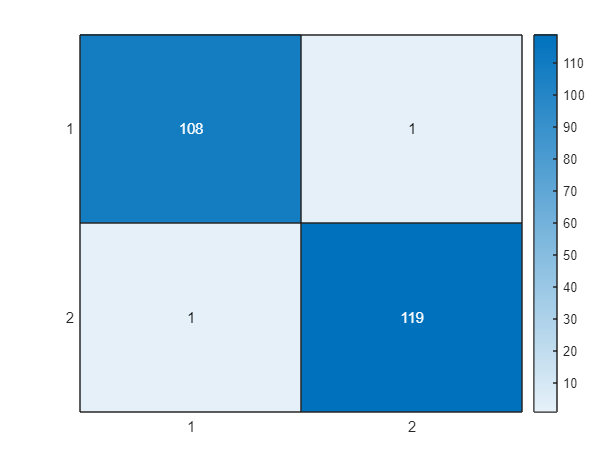

% Calculate yhat based on values calculated above
yhat = zeros(size(test,1),1);
for i = 1:size(test, 1)
    yhat(i) = round(prediction(table2array(test(i,:)), beta)) + 1;
end

% Confusion matrix
cmat = confusionmat(table2array(test(:,"label")), yhat);
heatmap(cmat);

As a final step, make the code general to accept any number of input features. Test with a random integer for *n_features* between 3 and 10.

Supporting Functions

function yhat = prediction(row, beta) % Performs the linear regression model to predict the yhat value based on the inputs beta and the regressed values x
    x = row(1:2);
    yhat = beta(1) + beta(2)*x(1) + beta(3)*x(2);
    yhat = 1.0 / (1.0 + exp(-yhat));
end